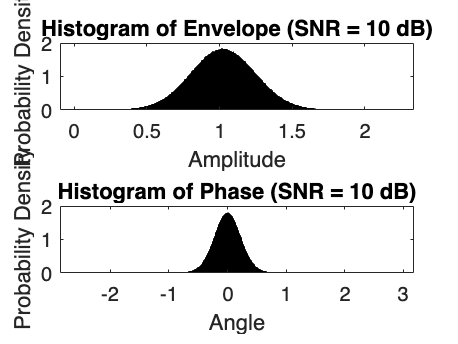

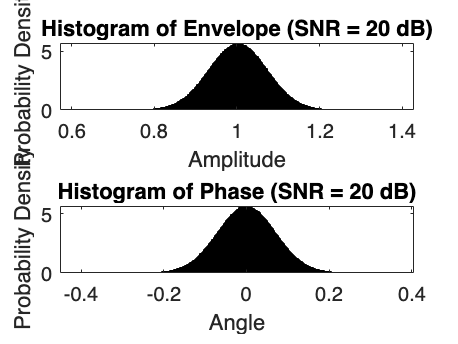

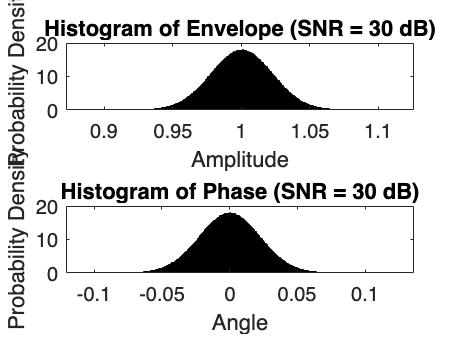

clc
clear
close all

% question 5 

%% part 1 

SNR = 10:2:30;
SNR_values_to_plot = [10, 20, 30];
N = 10^7;

A = 1;

n_I_realizations = zeros(length(SNR), N);
n_Q_realizations = zeros(length(SNR), N);

P_TH = zeros(size(SNR));

for i = 1:length(SNR)
    delta_squared = 10^(-SNR(i)/10); 
    n_I = sqrt(delta_squared/2) * randn(1, N);
    n_Q = sqrt(delta_squared/2) * randn(1, N);
    n = n_I + 1i * n_Q;
    
    x_env = abs(A + n);
    x_ph = angle(A + n); 
    
    if ismember(SNR(i), SNR_values_to_plot)
        figure;

        subplot(2, 1, 1);
        histogram(x_env, 'Normalization', 'pdf');
        title(['Histogram of Envelope (SNR = ', num2str(SNR(i)), ' dB)']);
        xlabel('Amplitude');
        ylabel('Probability Density');

        subplot(2, 1, 2);
        histogram(x_ph, 'Normalization', 'pdf');
        title(['Histogram of Phase (SNR = ', num2str(SNR(i)), ' dB)']);
        xlabel('Angle');
        ylabel('Probability Density');
    end



    P_TH(i) = log10(sum(abs(x_ph) > 10 * pi/180) / N);
    reduction_in_error = diff(P_TH);
    
end

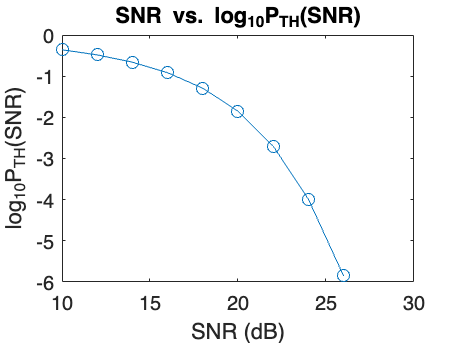


%part 2
    figure
    plot(SNR, P_TH, 'o-');
    title('SNR vs. log_{10}P_{TH}(SNR)');
    xlabel('SNR (dB)');
    ylabel('log_{10}P_{TH}(SNR)');

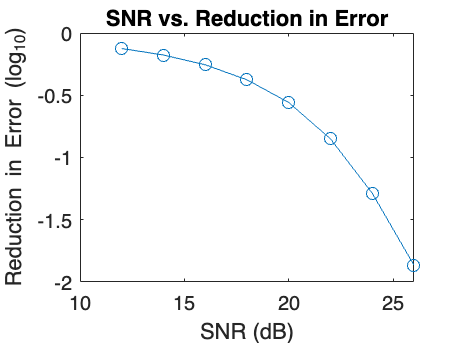


%part 3
    
    
    plot(SNR(2:end), reduction_in_error, 'o-');
    title('SNR vs. Reduction in Error');
    xlabel('SNR (dB)');
    ylabel('Reduction in Error (log_{10})');